%% dSub NLX screening sandbox


% this is a simple sandbox for loading, and checking the spatial tuning
% properties of cells using NLX



%% add some code to the path
warning off 

if ~isunix
    addpath(genpath('C:\Users\williamslab\Documents\github\vandermeerlab\code-matlab\shared'));
    
    addpath(genpath('C:\Users\williamslab\Documents\github\CEH2'));
    data_dir = 'C:\Users\williamslab\Dropbox (Williams Lab)\Williams Lab Team Folder\Eric\dSubiculum\inProcess\M23_2021-07-02_OF';
    
else
    addpath(genpath('/home/williamslab/Documents/Github/CEH2'));
    addpath(genpath('/home/williamslab/Documents/Github/vandermeerlab/code-matlab/shared'));
    data_dir = '/home/williamslab/Dropbox (Williams Lab)/Williams Lab Team Folder/Eric/dSubiculum/inProcess/M23_2021-07-02_OF';
end

warning on
cd(data_dir); % go to the data folder specified above

%% load dada
cfg.getTTnumbers = 0;
S = LoadSpikes(cfg);

WARNING in LoadSpikes: unrecognized config field(s) openNewFig
LoadSpikes: Loading 1 files...




pos = MS_LoadPos([]);

LoadPos.m: 100.00% of samples tracked.



% interpolate the spikes to match the time vector
spk_x = interp1(pos.tvec,pos.data(1,:),S.t{1},'linear');
spk_y = interp1(pos.tvec,pos.data(2,:),S.t{1},'linear');


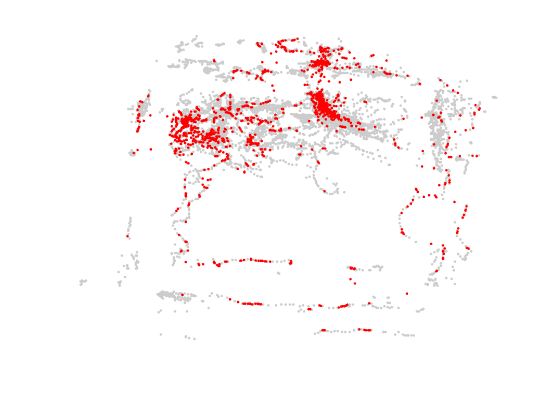

%% plot the position

figure(101)

plot(pos.data(1,:), pos.data(2,:), '.', 'color', [0.8 0.8 0.8]);
hold on


S_idx = nearest_idx(S.t{1}, pos.tvec);


plot(spk_x,spk_y, '.r')
axis off

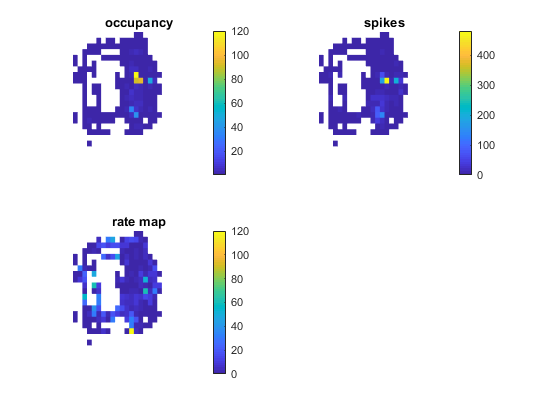

%% convert to heat map. 

% set up bins
SET_xmin = 80; SET_ymin = 0; % set up bins
SET_xmax = 660; SET_ymax = 520;
SET_xBinSz = 20; SET_yBinSz = 20;
 
x_edges = SET_xmin:SET_xBinSz:SET_xmax;
y_edges = SET_ymin:SET_yBinSz:SET_ymax;
 


% compute occupancy
occ_hist = histcn(pos.data(1:2,:)',y_edges,x_edges); % 2-D version of histc()
 
no_occ_idx = find(occ_hist == 0); % NaN out bins never visited
occ_hist(no_occ_idx) = NaN;
 
occ_hist = occ_hist .* (1/30); % convert samples to seconds using video frame rate (30 Hz)
 
subplot(2,2,1)
pcolor(occ_hist); shading flat; axis off; colorbar
title('occupancy');

% get the spike map
spk_hist = histcn([spk_x, spk_y],y_edges,x_edges);
 
spk_hist(no_occ_idx) = NaN;
 
subplot(222)
pcolor(spk_hist); shading flat; axis off; colorbar
title('spikes');

% rate map
tc = spk_hist./occ_hist;
 
subplot(223)
pcolor(tc); shading flat; axis off; colorbar
title('rate map');

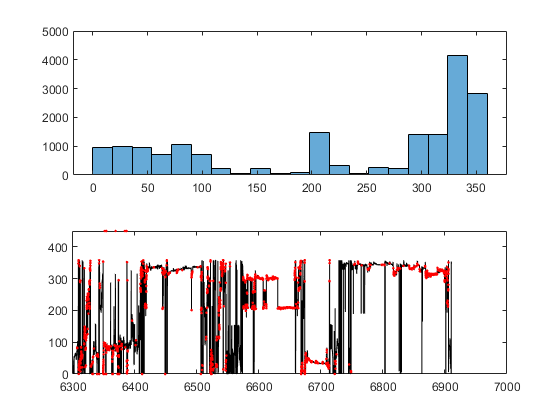

%% New Cell (heading info) 

hd_bin = 360/20;
hd_vec = 0:hd_bin:360;

keep_idx = pos.data(3,:)<=360;


figure(100)
subplot(2,1,1)
histogram(pos.data(3,keep_idx), hd_vec)
subplot(2,1,2)
plot(pos.tvec(keep_idx),pos.data(3,keep_idx), 'k')
hold on
plot(pos.tvec(S_idx), pos.data(3,S_idx), '.r')

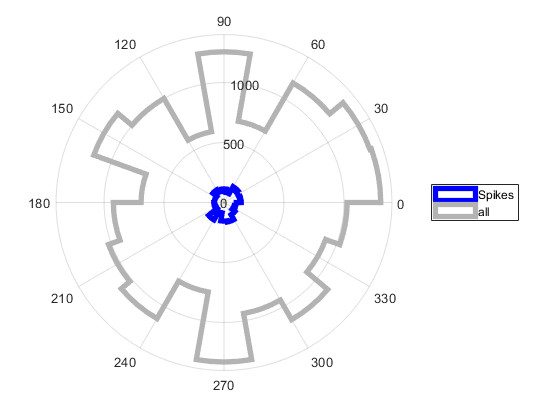

%% compute HD

figure()
polarhistogram(pos.data(3,S_idx),360/20, 'DisplayStyle','stairs', 'edgecolor', 'b', 'linewidth', 4);
hold on

polarhistogram(pos.data(3,:), 360/20,  'DisplayStyle','stairs', 'edgecolor', [0.7 0.7 0.7], 'linewidth', 4)

legend({'Spikes', 'all'})

## Look at PSDs

## Load CSC

cfg.fc = {'CSC5.ncs'}

cfg = struct with fields:
              fc: {'CSC5.ncs'}
    getTTnumbers: 0
      openNewFig: 0


csc= MS_LoadCSC(cfg)

WARNING in MS_LoadCSC: unrecognized config field(s) getTTnumbers, openNewFig
MS_LoadCSC: Loading 1 file(s)...
MS_LoadCSC: CSC5.ncs 1/2383 bad blocks found (0.04%).


csc = struct with fields:
     type: 'tsd'
    units: 'V'
     tvec: [1219927×1 double]
     data: [1×1219927 double]
    label: {'CSC5.ncs'}
      cfg: [1×1 struct]


## Plot LFP

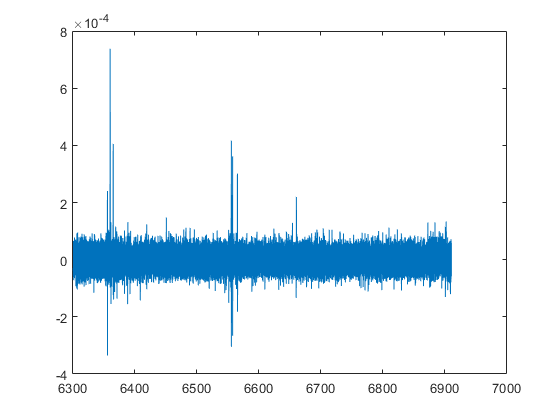

figure
plot(csc.tvec,csc.data)

## PSD

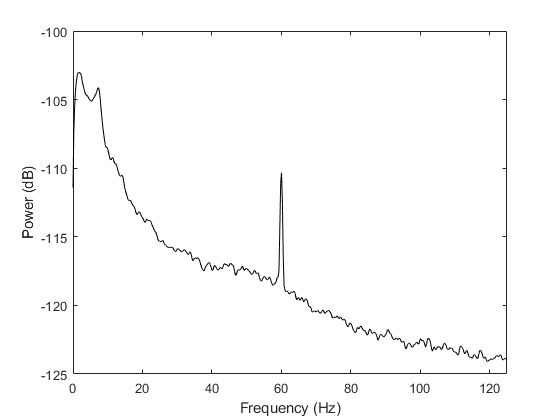

wSize = 2^12;
Fs= csc.cfg.hdr{1}.SamplingFrequency;
[Pxx,F] = pwelch(csc.data,hamming(wSize),wSize/2,wSize*2,Fs);
plot(F,10*log10(Pxx),'k'); xlabel('Frequency (Hz)'); ylabel('Power (dB)');
xlim([0 125])

## Theta filter

% filters
cfg_t.filt.type = 'cheby1'; %Cheby1 is sharper than butter
cfg_t.filt.f  = [6 12]; % broad, could use 150-200?
cfg_t.filt.order = 3; %type filter order (fine for this f range)
cfg_t.filt.display_filter =0; % use this to see the fvtool

T_csc = FilterLFP(cfg_t.filt, csc)

FilterLFP.m: reported Fs 2000.00, median tvec Fs 2000.00.
FilterLFP.m: filtering signal 1/1...


T_csc = struct with fields:
     type: 'tsd'
    units: 'V'
     tvec: [1219927×1 double]
     data: [1×1219927 double]
    label: {'CSC5.ncs'}
      cfg: [1×1 struct]



%% plot(cscR.tvec,cscR.data,'b',cscR.tvec,y,'r')
figure(1)
c_ord = linspecer(5)

c_ord =     0.3467    0.5360    0.6907
    0.9153    0.2816    0.2878
    0.4416    0.7490    0.4322
    1.0000    0.5984    0.2000
    0.6769    0.4447    0.7114


plot(csc.tvec,csc.data,'k')

Error using newplot (line 80)
Adding Cartesian plot to polaraxes is not supported.

Error in matlab.graphics.internal.newplotwrapper (line 12)
axReturn = newplot(varargin{:});

Error in 

hold on 
plot(T_csc.tvec,T_csc.data, 'color', c_ord(1,:), "LineWidth", 2)

## Phase and Amplitude Extraction

T_power = abs(hilbert(T_csc.data));
T_phase = angle(hilbert(T_csc.data));
plot(T_csc.tvec,T_power, 'color', c_ord(2,:), "LineWidth", 4)
plot(T_csc.tvec,T_phase/100000);
xlim([6500 6501]);

## Coherence

cfg.fc = {'CSC15.ncs'}
csc15= MS_LoadCSC(cfg)
[Cxx,CF] = mscohere(csc.data,csc15.data,hamming(wSize),wSize/2,wSize*2,Fs);

figure(3)
plot(CF,Cxx)
xlim([0 100])
